# FitParametrizedVectorCurve

Fits a parametric vector path. This fit treats all three coordinates as observations with normal uncorrelated uncertainty. In effect, it minimizes the residuals in all three coordinates. A weighted version is possible for a case in which say x-coordinates were measured more accurately than y and z coordinates. The trick here is to create a single scalar function incorporating all three coordinates to feed to `fitnlm` which is coded to only accept a scalar function.

Author: D. Carlsmith

Create a, say, ballistic trajectory.

clear;
ntimes=10;
g=[0,0,1]*9.8;% acceleration of gravity (row vector)
t=[0:.1:ntimes]';% times col vector
ndata=length(t);
x0=[0,0,0]; % initial position row vector
v0=[1,1,1]; % initial velocity row vector
x=x0+v0.*t+(1/2)*g.*t.^2+rand(ndata,3); % path array, one colum per coordinate
xt=[x(:,1);x(:,2);x(:,3)]; % path reshaped into one long column vector
tt=[t;t;t];% corresponding long column vector of times
ct1=[ones(ndata,1);zeros(ndata,1);zeros(ndata,1)];% coordinate logical
ct2=[zeros(ndata,1);ones(ndata,1);zeros(ndata,1)];% coordinate logical
ct3=[zeros(ndata,1);zeros(ndata,1);ones(ndata,1)];% coordinate logical
X=table(ct1,ct2,ct3,tt,xt);% columns are coordinate logicals, predictor time, and value
beta0=[x0';v0';g'];% parameter initial values

Make model function using the coordinate logicals to turn on and off parts of the single model function.

modelfun = @(b,a)( ...
a(:,1).*(b(1)+b(2).*a(:,4)+b(3)*a(:,4).^2)+...
a(:,2).*(b(4)+b(5).*a(:,4)+b(6)*a(:,4).^2)+...
a(:,3).*(b(7)+b(8).*a(:,4)+b(9)*a(:,4).^2)...
      );

Fit using a full nonlinear fitter `fitnlm` providing it the table of logicals and times and observations, and the initial parameters, along with the name of the model function. The fitting function `fitnlm` will call the model function with parameters b initially set to beta0 and change the parameters to try to match the observations. Note that we fit for components of the vector g/2 not g.

model=fitnlm(X,modelfun,beta0)

model = Nonlinear regression model:
    xt ~ (ct1*(b1 + b2*tt + b3*tt^2) + ct2*(b4 + b5*tt + b6*tt^2) + ct3*(b7 + b8*tt + b9*tt^2))

Estimated Coefficients:
           Estimate        SE         tStat       pValue  
          __________    _________    _______    __________

    b1       0.28343      0.08353     3.3932    0.00078574
    b2        1.0773     0.038605     27.906    1.2603e-84
    b3    -0.0065315    0.0037356    -1.7484      0.081431
    b4        0.5498      0.08353     6.5821     2.127e-10
    b5       0.98586     0.038605     25.537    1.3472e-76
    b6    0.00090257    0.0037356    0.24161       0.80925
    b7       0.46763      0.08353     5.5984    4.9633e-08
    b8        1.0279     0.038605     2

bfit  = model.Coefficients.Estimate ; % save parameters
xfit = [  bfit(1)+bfit(2)*t+bfit(3)*t.*t ];
yfit = [  bfit(4)+bfit(5)*t+bfit(6)*t.*t ];
zfit = [  bfit(7)+bfit(8)*t+bfit(9)*t.*t ];
xdat = x(:,1);ydat = x(:,2);zdat = x(:,3);

Plot the observations and fit.

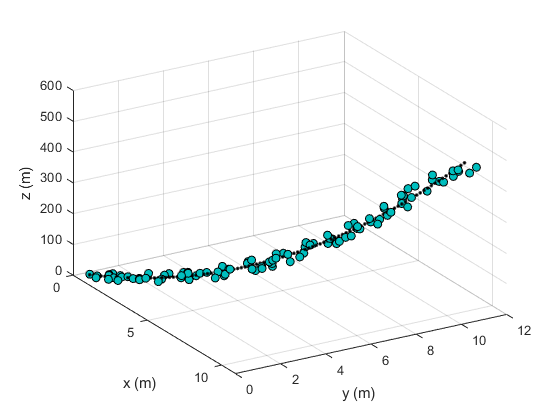

scatter3(xdat,ydat,zdat,'MarkerEdgeColor','k','MarkerFaceColor',[0 .75 .75])
hold on;
scatter3(xfit,yfit,zfit,'.','MarkerEdgeColor','k','MarkerFaceColor',[0 .75 .75])
xlabel('x (m)');ylabel('y (m)');zlabel('z (m)');
view(-30,10)
view([59 32])

## End of script